## Finding Spectral Components

A signal might be composed of one or more frequency components. The ability to observe all the spectral components depends on the frequency resolution of your analysis. ***The frequency resolution or resolution bandwidth of the power spectrum is defined as R = Fs/N, where N is the length of the signal observation.*** Only spectral components separated by a frequency larger than the frequency resolution will be resolved.

**Analyzing a Building's Earthquake Vibration Control System** 

Active Mass Driver (AMD) control systems are used to reduce vibration in a building under an earthquake. An active mass driver is placed on the top floor of the building and, based on displacement and acceleration measurements of the building floors, a control system sends signals to the driver so that the mass moves to attenuate ground disturbances. Acceleration measurements were recorded on the first floor of a three story test structure under earthquake conditions. Measurements were taken without the active mass driver control system (open loop condition), and with the active control system (closed loop condition).

Load the acceleration data and compute the power spectrum for the acceleration of the first floor. The length of the data vectors is 10e3 and the sample rate is 1 kHz. Use **pwelch** with segments of length 64 data points to obtain floor(10e3/64) = 156 FFT averages and a resolution bandwidth of Fs/64 = 15.625 Hz. As was shown before, averaging reduces noise effects and yields more accurate power measurements. Use 512 FFT points. Using NFFT > N effectively interpolates frequency points rendering a more detailed spectrum plot (this is achieved by appending NFFT-N zeros at the end of the time signal and taking the NFFT-point FFT of the zero padded vector).

The open loop and close loop acceleration power spectra show that when the control system is active, the acceleration power spectrum decreases between 4 and 11 dB. The maximum attenuation occurs at about 23.44 kHz. An 11 dB reduction means that the vibration power is reduced by a factor of 12.6. The total power is reduced from 0.1670 to 0.059 watts, a factor of 2.83.

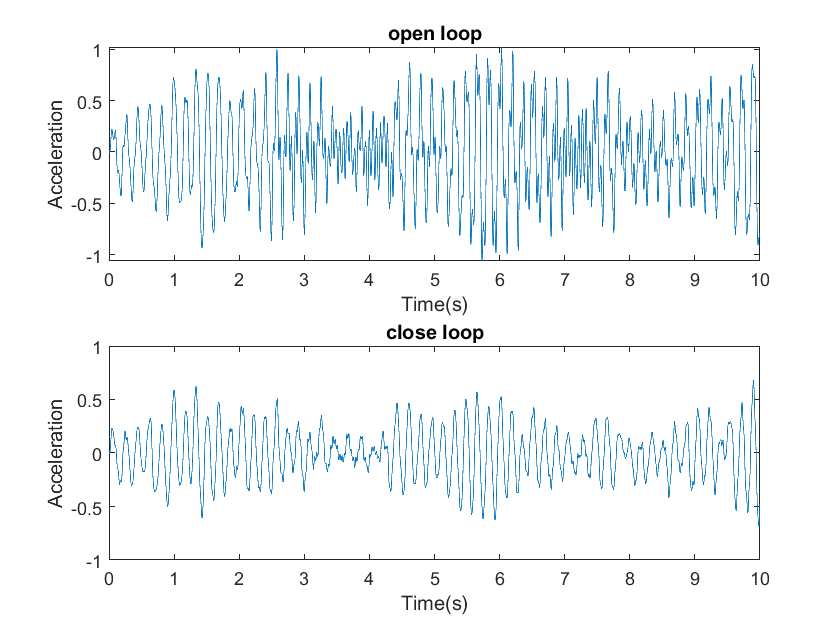

clc
clear
close all

load quakevibration.mat

Fs = 1e3;                 % sample rate
N=length(gfloor1OL);

t=0:1/Fs:(1-1/N)*N/Fs;

figure;
subplot(2,1,1)
plot(t,gfloor1OL);
xlabel('Time(s)');
ylabel('Acceleration')
title('open loop')

subplot(2,1,2)
plot(t,gfloor1CL);
xlabel('Time(s)');
ylabel('Acceleration')
title('close loop')

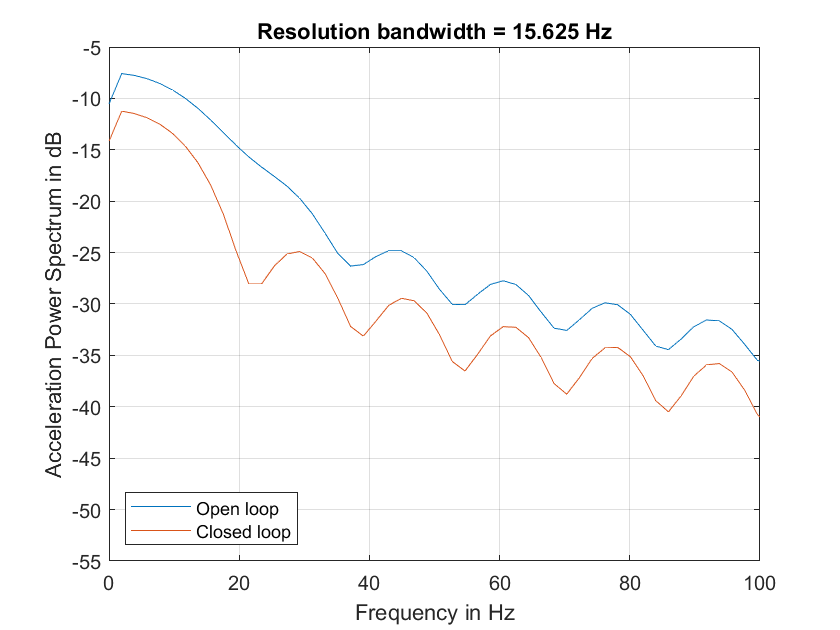


NFFT = 512;               % number of FFT points
segmentLength = 64;       % segment length

% open loop acceleration power spectrum
[P1_OL,F] = pwelch(gfloor1OL,ones(segmentLength,1),0,NFFT,Fs,'power'); 

% closed loop acceleration power spectrum
P1_CL     = pwelch(gfloor1CL,ones(segmentLength,1),0,NFFT,Fs,'power'); 

helperFrequencyAnalysisPlot2(F,10*log10([(P1_OL) (P1_CL)]),...
  'Frequency in Hz','Acceleration Power Spectrum in dB',...
  'Resolution bandwidth = 15.625 Hz',{'Open loop', 'Closed loop'},[0 100])

You are analyzing vibration data and you know that vibrations have a cyclic behavior. Then how is it that the spectrum plots shown above do not contain any sharp spectral lines typical of cyclic behavior? Maybe you are missing those lines because they are not resolvable with the resolution obtained with 64 point segment lengths? Increase the frequency resolution to see if there are spectral lines that were not resolvable before. Do this by increasing the data segment length used in the **pwelch** function to 512 points. This yields a new resolution of Fs/512 = 1.9531 Hz. In this case, the number of FFT averages is reduced to floor(10e3/512) = 19. Clearly, there is a trade-off between number of averages and frequency resolution when using **pwelch**. Keep the number of FFT points equal to 512.

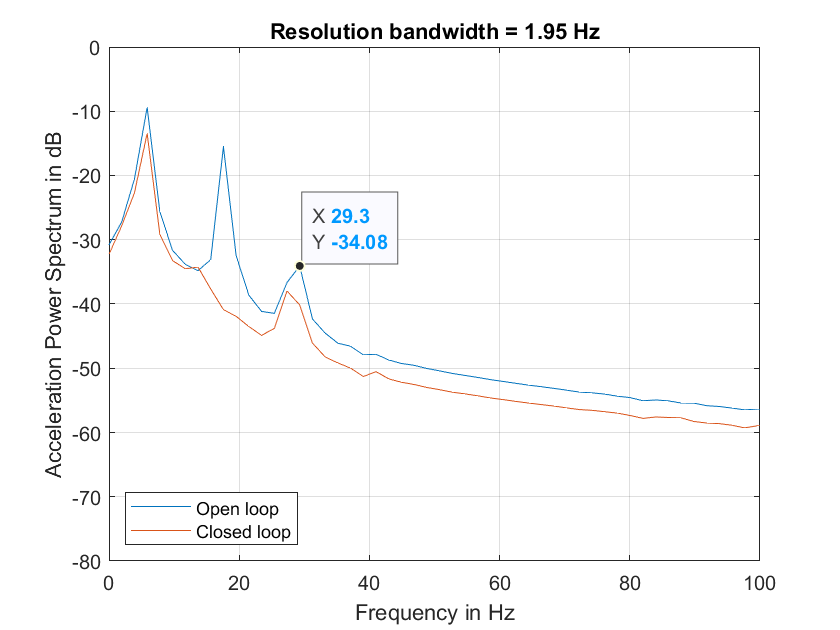

NFFT = 512;            % number of FFT points
segmentLength = 512;   % segment length

[P1_OL,F] = pwelch(gfloor1OL,ones(segmentLength,1),0,NFFT,Fs,'power'); 
P1_CL     = pwelch(gfloor1CL,ones(segmentLength,1),0,NFFT,Fs,'power'); 

helperFrequencyAnalysisPlot2(F,10*log10([(P1_OL) (P1_CL)]),...
  'Frequency in Hz','Acceleration Power Spectrum in dB',...
  'Resolution bandwidth = 1.95 Hz',{'Open loop', 'Closed loop'},[0 100])

Notice how the increase in frequency resolution allows you to observe three peaks on the open loop spectrum and two on the close loop spectrum. These peaks were not resolvable before. The separation between the peaks on the open loop spectrum is about 11 Hz which is smaller than the frequency resolution obtained with segments of length 64 but larger than the resolution obtained with segments of length 512. The cyclic behavior of the vibrations is now visible. The main vibration frequency is at 5.86 Hz, and the equispaced frequency peaks suggest that they are harmonically related. While it has already been observed that the control system reduces the overall power of the vibrations, the higher resolution spectra shows that another effect of the control system is to notch the harmonic component at 17.58 Hz. So the control system not only reduces the vibration but also brings it closer to a sinusoid.

It is important to note that frequency resolution is determined by the number of signal points, not by the number of FFT points. Increasing the number of FFT points interpolates the frequency data to give you more details on the spectrum but it does not improve resolution. 